## 2.2.1

### PROBLEM 3.

#### <PART 2>

Choose a partial Fourier Series Approximation and plot $f\left(t\right)$and $p_n \left(t\right)$on the same graph

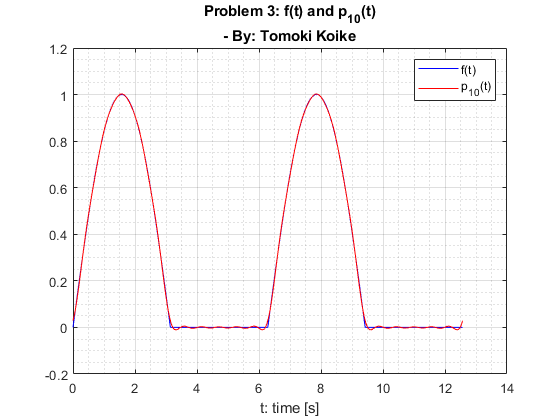

% Defining f(t)
prp = 2*pi; % Pulse repitetion period
pw = pi; % Pulse width
fs = 1000; % Sample frequency
period = 2*pi*2; % Period to plot graph
T = 0:1/fs:period-1/fs; % Time to map t
D = 0:prp:period-prp; % Delay
f = pulstran(T,D,@(t)sin(t).*(t>=0).*(t<pw));

% Another method of defining f(t)
% t = linspace(0, 2*pi*3, 10^4);
% f = sin(t) .* heaviside(sin(t));

% Defining partial Fourier Series Approximation @ k = 10
t = linspace(0, 2*pi*2, 10^5); % Defining time t
p_10 = 1 / pi + 0.5 * sin(t);
for k = 2:2:10
    p_10 = p_10 - 2/pi/(k^2-1)*cos(k.*t);
end

% Plotting 
figure(1)
plot(T, f, '-b')
xlabel('t: time [s]')
title({'Problem 3: f(t) and p_1_0(t)','- By: Tomoki Koike'})
grid on
grid minor
box on
hold on 
plot(t, p_10, '-r')
hold off
legend('f(t)', 'p_1_0(t)')

Compute the error 

% Calculating the error
a = [-1i/4, 1/pi, 1i/4, -1/pi./((2:2:100000000-3).^2-1)]; % Vectorizing a_k
e_10 = 2 * norm(a(11:length(a))); 
% The error for || f(t) - p_10(t) || is going to be
disp(e_10);

    0.0045



Plot the power spectrum for $f$. Compute the root mean square of $f$, that is, compute the norm 

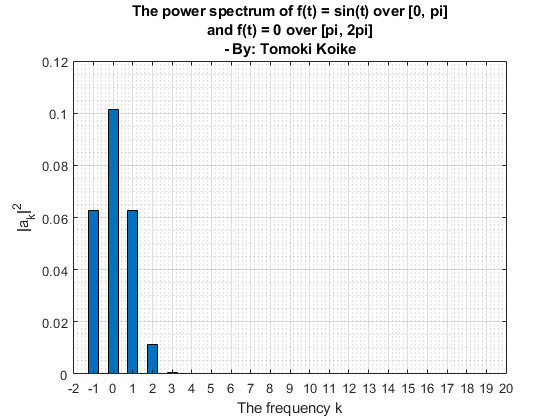

figure(2)
bar((0:20), abs(a(1:21).^2), 0.5)
xticks([-1 0 1, (2:21)])
xticklabels({'-2','-1','0','1','2','3','4','5','6','7','8','9','10'...
    ,'11','12','13','14','15','16','17','18','19','20'})
grid on 
grid minor
box on
xlabel('The frequency k'); ylabel('|a_k|^2')
title({'The power spectrum of f(t) = sin(t) over [0, pi]', ...
    'and f(t) = 0 over [pi, 2pi]','- By: Tomoki Koike'})


% Calculating the root mean square
% Defining f(t)
prp = 2*pi; % Pulse repitetion period
pw = pi; % Pulse width
fs = 1000; % Sample frequency
period = 2*pi; % Period to plot graph
T = 0:1/fs:period-1/fs; % Time to map t
D = 0:prp:period-prp; % Delay
f = pulstran(T,D,@(t)sin(t).*(t>=0).*(t<pw));

% The root mean square is 
rootMeanSqr = rms(f);
disp(rootMeanSqr);

    0.5000

